
len = 4;%(p theta phi rho);
lb = [0 -pi -pi/2 0];
ub = [inf pi pi/2 inf];
function obj = Objctive(m)
R = 300.4;
obj = (m(4) - R)^2;
end

function con = constrict1(m)
%约束1:点在抛物面上
R = 300.4;
F = 0.466;
r1 = (1-F)*R;
con = optimconstr(1);
con(1) = (m(4)^2*cos(m(3))^2)/(2*m(1)) - r1 - m(1)/2-m(4)*sin(m(3))==0;
end
function con = constrict2(m)
%约束2:点在R内
rr = 150;
con = optimconstr(1);
con(1) = m(4)^2*cos(m(3))^2<=rr^2;
end

% 创建优化变量
m2 = optimvar("m",len,"LowerBound",lb,"UpperBound",ub);

% 设置求解器的初始起点
initialPoint.m = zeros(size(m2));

% 创建问题
problem = optimproblem;

% 定义问题目标
problem.Objective = fcn2optimexpr(@Objctive,m2);

% 定义问题约束
problem.Constraints.constraint1 = constrict1(m2);
problem.Constraints.constraint2 = constrict2(m2);

% 设置非默认求解器选项
options = optimoptions("fmincon","Display","iter","PlotFcn","optimplotfval");

% 显示问题信息
show(problem);


  OptimizationProblem : 

	Solve for:
       m

	minimize :
       (m(4) - 300.4).^2


	subject to constraint1:
       arg_LHS == 0

       where:

             arg8 = (m(4) .* sin(m(3)));
             arg_LHS = (((((m(4).^2 .* cos(m(3)).^2) ./ (2 .* m(1))) - 160.4136) - (m(1) ./ 2)) - arg8);

	subject to constraint2:
       (m(4).^2 .* cos(m(3)).^2) <= 22500

	variable bounds:
               0 <= m(1)
       -3.141593 <= m(2) <= 3.1416
       -1.570796 <= m(3) <= 1.5708
           299.8 <= m(4) <= 301



将使用 fmincon 求解问题。
初始点 X0 不在边界 LB 和 UB 之间；
FMINCON 对 X0 进行了偏移以严格满足边界条件。

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       1    3.600000e-03    6.770e+04    1.998e-04
    1       2    3.567673e-01    6.738e+04    1.075e+00    5.373e-01
    2       3    3.599838e-01    6.738e+04    1.080e+00    2.825e-03
    3       4    3.599926e-01    4.579e+02    1.200e+00    1.562e+00
    4       9    3.599634e-01    4.379e+02    1.200e+00    1.469e-01
    5      13    3.599543e-01    2.365e+02    3.017e+00    3.085e-01
    6      14    3.599168e-01    7.426e+00    5.412e+00    8.187e-01
    7      15    3.597441e-01    7.821e+00    4.593e+00    6.247e-01
    8      17    3.259987e-01    3.086e+00    1.074e+00    1.412e+00
    9      26    8.140756e-02    3.266e+00    5.026e-01    2.087e+00
   10      35    2.005647e-03    1.587e+00    5.717e-02    2.277e+00
   11      37    4.884356e-05    5.052e-02  

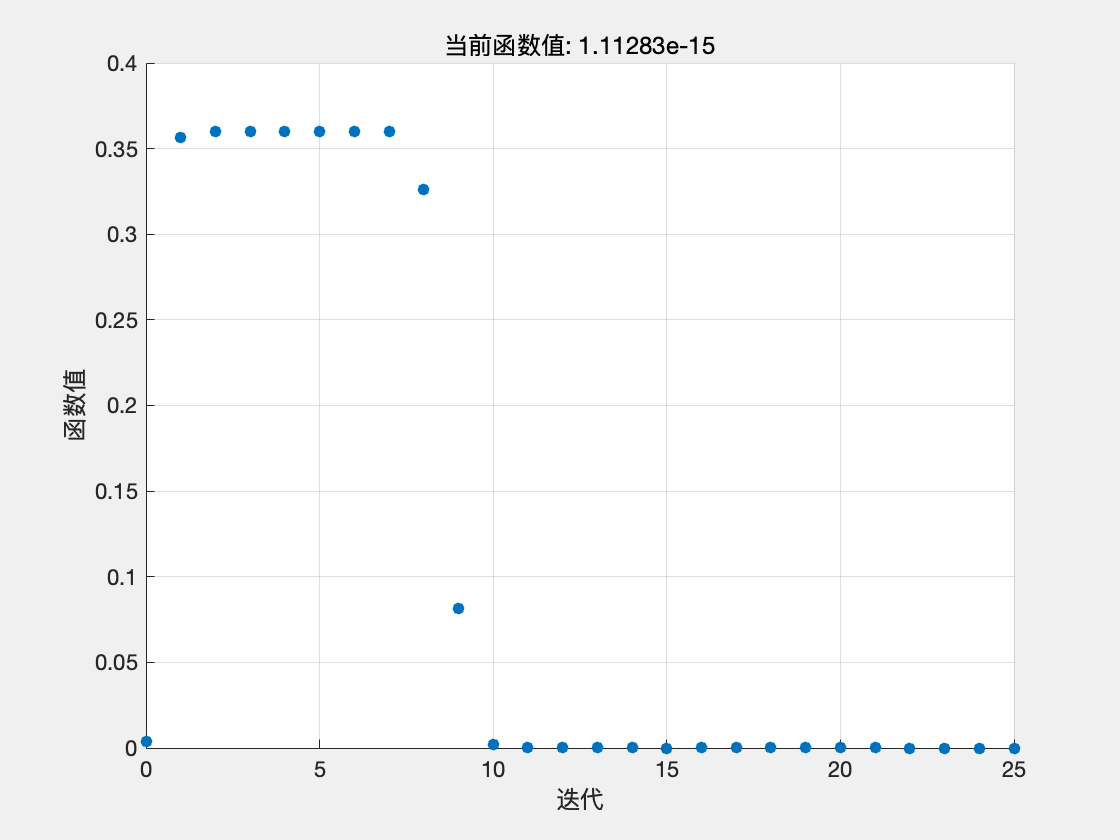


% 求解问题
[solution,objectiveValue,reasonSolverStopped] = solve(problem,initialPoint,...
    "Solver","fmincon","Options",options);


% 显示结果
solution

solution = 包含以下字段的 struct :
    m: [4×1 double]


reasonSolverStopped

reasonSolverStopped =     OptimalSolution


objectiveValue

objectiveValue = 1.1128e-15


% 清除变量
clearvars m2 initialPoint options reasonSolverStopped objectiveValue
solution.m

ans =    15.1406
   -0.0000
    1.1740
  300.4000


z_dingdian = -solution.m(1)/2-r1

z_dingdian = -167.7703


p = solution.m(1)

p = 15.1406

m = R - r1 - p/2;
